# Useful sur file functionality

This guide describes some useful functionality that can be applied to individual sur files.

Finding the maximum impact level

Let's use the organic solids sur file from the model endpoint

sur = run.solidsSur

sur =   Solids with properties:

      rawDataValueCol: 'outCol1'
    defaultPlotLevels: [4 192 1553 10000]
          defaultUnit: 'g m^{-2}'
                 path: 'C:\newdepomod_projects\bay_of_fish\depomod\results\bay_of_fish-1-NONE-N-solids-g0.depomodresultssur'
              rawData: [1×1 struct]
     interpolatedGrid: []
                    X: [80×1 double]
                    Y: [80×1 double]
                    Z: [80×80 double]
        GeoReferenced: 1

To find the maximum impact within the sur file

maxVal = sur.max

maxVal =                23801.51202

The units are g m-2, and so in this case, the result is 23.8 kg of solids per m2.

By specifying three outputs, the location of the maximum impact can also be discerned.

[maxVal, maxEasting, maxNorthing] = sur.max

maxVal =                23801.51202

maxEasting =                   350427.5

maxNorthing =                  1069122.5

## Calculate an area of impact

The area of the impact can be calculated. This requires a particular intensity level for the impact to be specified, e.g.:

sur.area(1)     % g m-2

ans =           311952.463618763

sur.area(250)   % g m-2

ans =           56878.5241655428

sur.area(1000)  % g m-2

ans =           42183.6459280066

If no intensity level is passed in, the function has no basis for discriminating what is or isnt an impact and simply returns to total area in the domain

sur.area()

ans =      3900625

To estimate the maximum areal extent of all deposition, the intensity passed can be some implausibly small level

sur.area(0.0001) % g m-2

ans =           751806.971272413

## Find the mean value over an area

The mean value within an area can be similarly derived

sur.mean(1)     % g m-2

ans =           1294.45817477698

sur.mean(250)   % g m-2

ans =           6951.57058963885

sur.mean(1000)  % g m-2

ans =           9213.74186800267

The average over the whole domain can be arrived at using:

sur.mean(0)

ans =           103.534942099183

## Calculate the total mass deposited within an impact

In order to calculate total masses, rather than per m2 masses, we can integrate over the spatial impact described in the sur file. To do this we use the `.volume()` method.

For example, if we want to know the total mass in the model domain as described by the sur file

sur.volume

ans =           403850983.525625

This integrates over the whole domain and returns the total mass, which in this case is just over 1 million kg of solids. Notice that this value is the same as that found within the run log file for the mass balance of solids over the course of the run (the balance in lieu of solids exported out of the domain)

run.log.Masses.solids.balance.run

ans = '403574534.9947'

These values are within a tenth of 1% of one another - differences are down to the different integration procedures used by NewDepomod and the Matlab toolbox.

We can also pass in an intensity level to the volume method to return the mass within the area above that intensity

sur.volume(250)

ans =            395395075.77125

So practically all of the mass is concentrated at intensities above 250 g m-2 (~97%) in this case.

## Find the value at a particular location

Finding the value at a particular location is useful if there are sensitive features to be protected or if model values are to be explicitly compared with seabed measurements. This can be done as follows:

sur.valueAt(350427,1069122) % easting, northing

ans =           24003.3606469149

A useful way to characterise the accuracy of a model output is to  determine how far - in spatial distance - a given location is from a particular value. This helps in cases where an impact is particularly steep and therefore errors in magnitude between modelled and sample values simply represent arguably smaller errors in location

sur.distanceToValue(350427,1069122, 250)

ans =            53.462100586592

In this case the nearest location with a value of 250 g m-2 is 53 m away from the specified location 

## Plot the spatial impact

The impact described by the sur file can be plotted with the context of the bathymetry and cages if the entire project/run information is available.

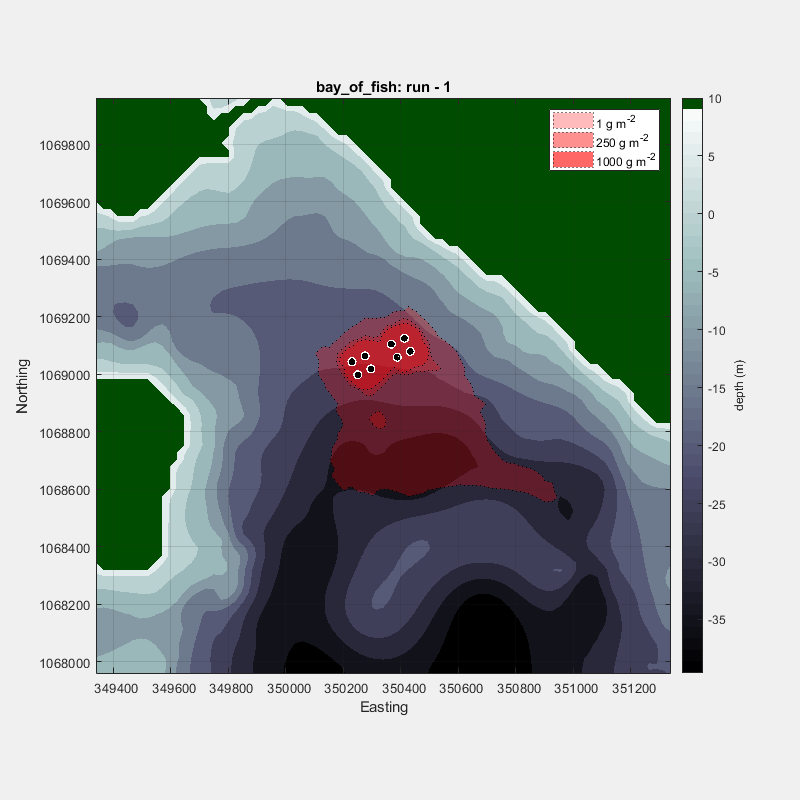

ans =   Figure (5) with properties:

      Number: 5
        Name: ''
       Color: [0.94 0.94 0.94]
    Position: [0 0 600 600]
       Units: 'points'

  Show all properties

run.plot('sur', sur, 'levels', [1 250 1000])

In cases where a sur file is being considered in isolation, a few other plotting methods can be used.

The `.plot() `function on the `Depomod.Sur` object can produce 3 types of plot

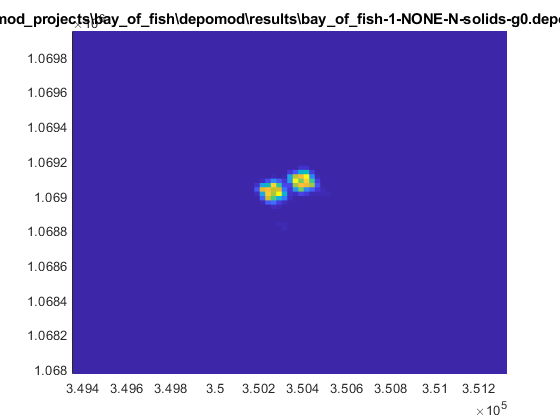


sur.plot('type','pcolor') % default in nothing passed in

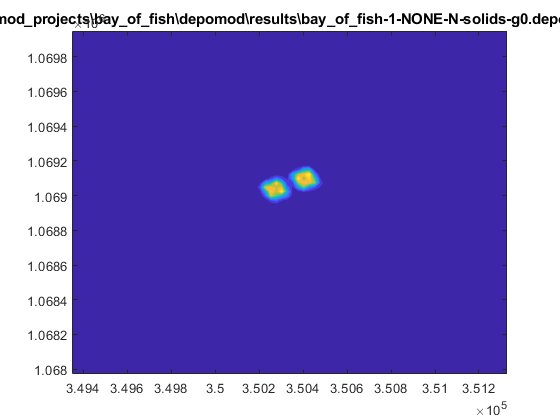

sur.plot('type','contour') 

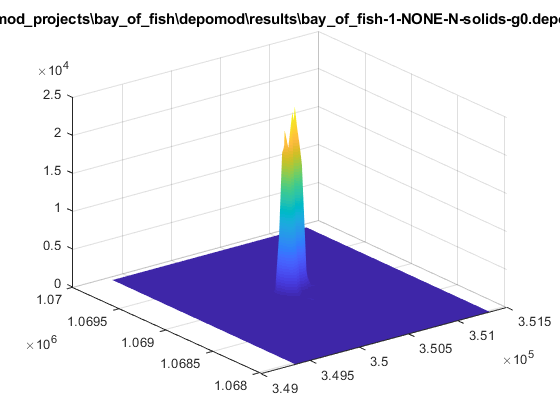

sur.plot('type','surf') 

These are useful for giving a quick idea of the impact and can be manipultated using the standard Matlab plotting functions, for example by altering the colourmap 

sur.plot('type','surf') 

% divide max by 10 so colourmap represent 10 g increments

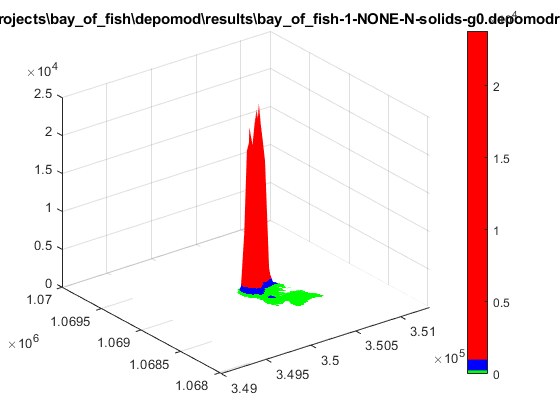

map = zeros(int32(ceil(sur.max)/10),3); 

% Adjust colourmap
for m = 1:1 % 0-10 g, white
    map(m,1:3) = [1 1 1];
end
for m = 2:25 % 10-250 g, green
    map(m,1:3) = [0 1 0];
end
for m = 26:100 % 250-1000 g, blue
    map(m,1:3) = [0 0 1];
end
for m = 101:size(map,1) % >1000 g, red
    map(m,1:3) = [1 0 0];
end

colormap(map);
colorbar;

## Generate impact contours

Contours can be generated from the sur file around specific impact levels

c = sur.contour(250)

c =                        250                  350527.5                  350502.5                  350477.5                  350452.5                  350427.5                  350402.5                  350377.5          350372.518057871                  350352.5          350349.203689191                  350327.5          350322.178289308                  350302.5                  350277.5           350256.98438347                  350252.5                  350227.5          350215.313341098                  350202.5          350198.564261821          350182.774056662          350177.751118321          350180.740502216                  350202.5          350208.084569674                  350227.5                  350252.5          350254.427463173                  350277.5                  350302.5                  350327.5          350330.590063681                  350352.5          350371.114207168                  350377.5                  350402.5                  350427.5        

This is a Matlab contour object describing the polygons of the contours around the specified impact level. This output can be used in further manipulations. For example, this output is used in the` .area()` function to calculcate impact level areas and is also used to plot the impact contours in the `.plot()` of the parent run, i.e.

## Other sur manipulations

The cell-by-cell values can be easily scaled by a desired factor. For example,

sur.scale(2)

will double all of the values, whereas

sur.scale(0.5)

will halve all of the values. This might be useful, for example, for experimenting with the effects of increasing or decreasing biomass, though care must be taken as the response of the spatial impact to changes in loading is not always linear.

Sur files can be "added" to each other. This is useful when modelling neighbouring sites and allows their overlapping impacts to be added together. The domains described by the two sur files need not be the same, the function will combine the two domains into a new expanded sur domain.

combinedSur = sur.add(otherSur)

The areas and intensities of the combined impact can then be derived using the functions described above.